addpath('./Sensitivities', './analyzeFlows', genpath('./utilities'))

# eulerian number of gain and loss volumes curve

Tag = 'WKY214_4dAffine_2';
configuration = Configuration3D(Tag);
eulerian = EulerianSpecification(Tag);

Error using importdata (line 139)
Unable to open file.

Error in EulerianSpecification.loadRomtResult (line 350)
            U = importdata(sprintf('%s/%s_v_%d_%d_t_%d.mat', ...

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('EulerianSpecification', 'C:\MATLAB\nonlinearDiffusionROMT\EulerianSpecification.m', 67)" style="font-weight:bold">EulerianSpecification</

eulerian.getPropertiesInMask;
numPositiveSource = zeros(1,configuration.nFiles);
numNegativeSource = zeros(1,configuration.nFiles);
T = 1:configuration.nFiles;
for i=1:configuration.nFiles
    numPositiveSource(i) = sum(eulerian.source(:,:,:,i)>0,"all");
    numNegativeSource(i) = sum(eulerian.source(:,:,:,i)<0,"all");
end
figure
plot(T,numPositiveSource,'-o',T,numNegativeSource,'-o');
legend('positive source','negative source')
ylabel('number of volumes')
xlabel('frame number')
title('number of positive source volumes vs. number of negative source volumes')

## intensity curve

Tag = 'WKY214_4dAffine_1';
configuration = Configuration3D(Tag);
configuration.plotVolume(configuration.data_start,configuration.data_end);

## Total intensity curve vs. interpolated intensity curve

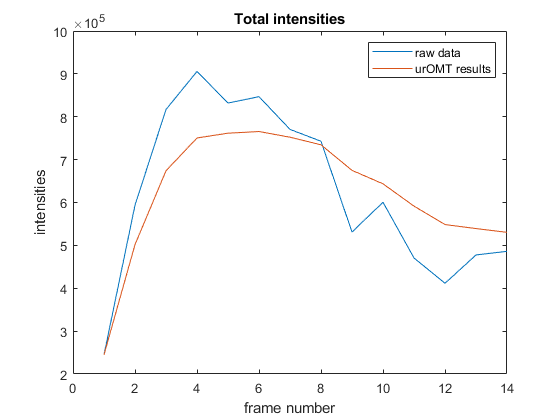

Tag = 'WKY215_4dAffine_largemask';
clear Xraw
configuration = Configuration3D(Tag);
configuration.loadVolume;
%Xraw = zeros(1,configuration.nFiles+1);
Xinterpolated = zeros(1,configuration.nFiles+1);
ti = configuration.timeInitial;
tj = configuration.timeJump;
tf = configuration.timeFinal;
count = 0;
for t1 = ti:tj:tf+tj
    count = count+1;
    if t1 == ti
        RHO{count} = readmatrix(sprintf('%s/rho_%s_%d_t_0.txt', ...
        configuration.pathOutput, configuration.tag, ti));
    else
        RHO{count} = importdata(sprintf('%s/%s_d_%d_%d_t_%d.mat', ...
        configuration.pathOutput, configuration.tag, ...
        t1 - tj, t1, (t1 - ti) ./ tj));
    end
end
if ~isempty(configuration.pathMask)
    mask = Mask(configuration.pathMask, configuration.xRange,...
                configuration.yRange, configuration.zRange);
    if configuration.do_resize
        mask = mask.resize(configuration.sizeFactor);
    end
end
for i=1:length(configuration.Data)
    A = reshape(configuration.Data(i).volume(:),configuration.trueSize);
    A(mask.contents == 0) = 0;
    B = reshape(RHO{i},configuration.trueSize);
    B(mask.contents == 0) = 0;
    B1{i} = B;
    Xraw(i) = sum(A,'all');
    Xinterpolated(i) = sum(B,'all');
    Xre215(i) = norm(A(:)-B(:))/norm(A(:));
end
  
figure
T=1:length(configuration.Data);
plot(T,Xraw,T,Xinterpolated);
legend('raw data','urOMT results')
ylabel('intensities')
xlabel('frame number')
title('Total intensities')

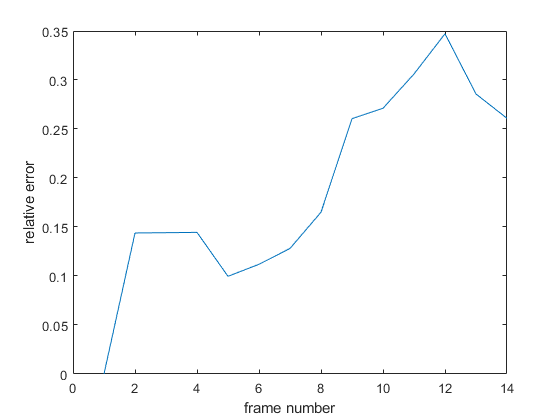

figure
plot(T,Xre215);
%plot(T,X14X15re)
ylabel('relative error')
xlabel('frame number')

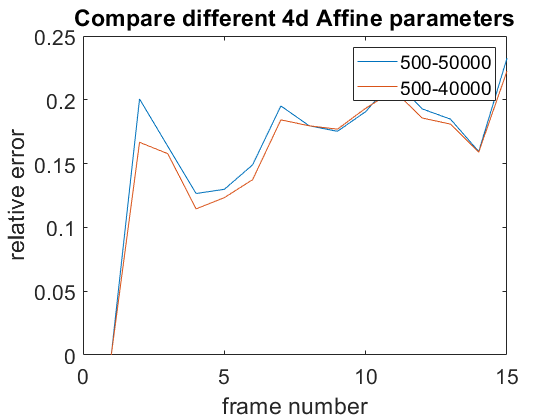

figure
plot(T,Xre11,T,Xre12)
legend('500-50000','500-40000')
ylabel('relative error')
xlabel('frame number')
title('Compare different 4d Affine parameters')
ax = gca; 
ax.FontSize = 16; 

## Speed curve

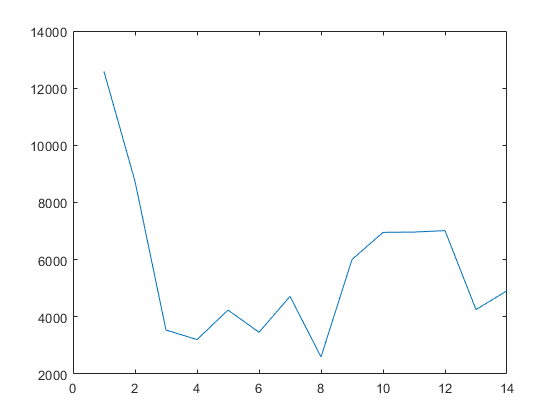

Tag = 'WKY214_4dAffine_t5';
configuration = Configuration3D(Tag);
vSum = zeros(1,configuration.nFiles);
ti = configuration.timeInitial;
tj = configuration.timeJump;
tf = configuration.timeFinal;
count = 0;
for t1 = ti:tj:tf
    count = count+1;
    velocity{count} = importdata(sprintf('%s/%s_v_%d_%d_t_%d.mat', ...
    configuration.pathOutput, configuration.tag, ...
    t1, t1 + tj, (t1 - ti) ./ tj + 1));
    velocity{count} = reshape(velocity{count},[configuration.trueSize,3,configuration.nt]);
    velocity{count} = squeeze(sqrt(velocity{count}(:,:,:,1,:).^2+velocity{count}(:,:,:,2,:).^2+velocity{count}(:,:,:,3,:).^2));
    velocity{count} = mean(velocity{count},4);
end
if ~isempty(configuration.pathMask)
    mask = Mask(configuration.pathMask, configuration.xRange,...
                configuration.yRange, configuration.zRange);
    if configuration.do_resize
        mask = mask.resize(configuration.sizeFactor);
    end
end
for i=1:length(configuration.Data)
    A = velocity{i};
    A(mask.contents == 0) = 0;
    v214t5(i) = sum(A,'all');
end
figure 
plot(v214t5)

T=1:14

T =      1     2     3     4     5     6     7     8     9    10    11    12    13    14


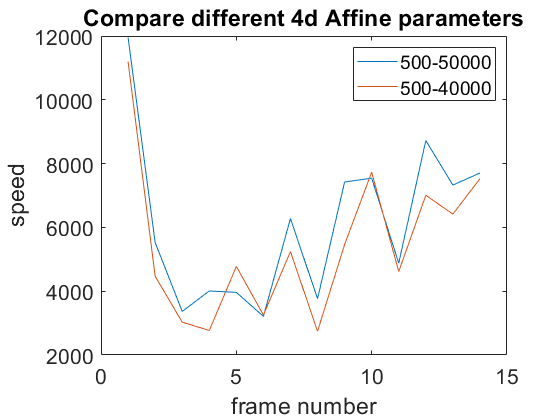

figure
plot(T,v11,T,v12)
legend('500-50000','500-40000')
ylabel('speed')
xlabel('frame number')
title('Compare different 4d Affine parameters')
ax = gca; 
ax.FontSize = 16; 

## calculate properties in mask

PATH_TO_PYTHON = '/Users/Kaiming Xu/anaconda3/envs/rOMT';
WKYTags = [
%    "WKY201_4dAffine_largemask";
%    "WKY202_4dAffine_largemask";
 %   "WKY203_4dAffine_largemask";
%    "WKY213_4dAffine_largemask";
%     "WKY214_4dAffine_11";
%     "WKY214_4dAffine_12";
%     "WKY214_4dAffine_14";
%     "WKY214_4dAffine_15";    
%     "WKY214_4dAffine_17";
%     "WKY214_4dAffine_18";
%     "WKY214_4dAffine_19";
    "WKY214_4dAffine_t.5";
    "WKY214_4dAffine_t2";
    "WKY214_4dAffine_t5";    
%    "WKY215_4dAffine_largemask";
    ];
SHRSPTags = [
   "SHRSP205_4dAffine_largemask";
   "SHRSP207_4dAffine_largemask";
   "SHRSP209_4dAffine_largemask";
   "SHRSP210_4dAffine_largemask";
   "SHRSP212_4dAffine_largemask";
    ];
addpath('./Sensitivities', './analyzeFlows', genpath('./utilities'))
for ii = 1:length(WKYTags)
    obj = Configuration3D(WKYTags(ii));
%    sigmalabels{ii} = sprintf("%d",obj.sigmaFunctionConstant);
    if ~isempty(obj.pathMask)
        csfMask = Mask(obj.pathMask, obj.isMaskFilled, obj.xRange,...
                    obj.yRange, obj.zRange);
        if obj.do_resize
            csfMask = csfMask.resize(obj.sizeFactor);
        end
    end
    [scalarMap,~] = runPostprocessing(WKYTags(ii), PATH_TO_PYTHON);
    scalarMap.speed(csfMask.contents==0) = 0;
    scalarMap.flux(csfMask.contents==0) = 0;
    scalarMap.Pe(csfMask.contents==0) = 0;
    scalarMap.diffusionCoefficient(csfMask.contents==0) = 0;
%    wkydCoeff(ii) = sum(scalarMap.diffusionCoefficient(scalarMap.diffusionCoefficient>0),'all')/sum(scalarMap.diffusionCoefficient>0,'all');
    wkySpeed(ii) = sum(scalarMap.speed(scalarMap.speed>0),'all')/sum(scalarMap.speed>0,'all');
    wkyFlux(ii) = sum(scalarMap.speed>0,'all');
    wkyPe(ii) = sum(scalarMap.Pe(scalarMap.Pe>0),'all')/sum(scalarMap.Pe>0,'all');
end

t = 1 (t1 = 9, t2 = 1 -> T = 9.000)
t = 2 (t1 = 9, t2 = 2 -> T = 9.200)
t = 3 (t1 = 9, t2 = 3 -> T = 9.400)
t = 4 (t1 = 9, t2 = 4 -> T = 9.600)
t = 5 (t1 = 9, t2 = 5 -> T = 9.800)
t = 6 (t1 = 9, t2 = 6 -> T = 10.000)
t = 7 (t1 = 9, t2 = 7 -> T = 10.200)
t = 8 (t1 = 9, t2 = 8 -> T = 10.400)
t = 9 (t1 = 9, t2 = 9 -> T = 10.600)
t = 10 (t1 = 9, t2 = 10 -> T = 10.800)
t = 11 (t1 = 11, t2 = 1 -> T = 11.000)
t = 12 (t1 = 11, t2 = 2 -> T = 11.200)
t = 13 (t1 = 11, t2 = 3 -> T = 11.400)
t = 14 (t1 = 11, t2 = 4 -> T = 11.600)
t = 15 (t1 = 11, t2 = 5 -> T = 11.800)
t = 16 (t1 = 11, t2 = 6 -> T = 12.000)
t = 17 (t1 = 11, t2 = 7 -> T = 12.200)
t = 18 (t1 = 11, t2 = 8 -> T = 12.400)
t = 19 (t1 = 11, t2 = 9 -> T = 12.600)
t = 20 (t1 = 11, t2 = 10 -> T = 12.800)
t = 21 (t1 = 13, t2 = 1 -> T = 13.000)
t = 22 (t1 = 13, t2 = 2 -> T = 13.200)
t = 23 (t1 = 13, t2 = 3 -> T = 13.400)
t = 24 (t1 = 13, t2 = 4 -> T = 13.600)
t = 25 (t1 = 13, t2 = 5 -> T = 13.800)
t = 26 (t1 = 13, t2 = 6 -> T = 14.000)
t = 27 (

print('haha')
for ii = 1:length(SHRSPTags)
    obj = Configuration3D(SHRSPTags(ii));
%    sigmalabels{ii} = sprintf("%d",obj.sigmaFunctionConstant);
    if ~isempty(obj.pathMask)
        csfMask = Mask(obj.pathMask, obj.isMaskFilled, obj.xRange,...
                    obj.yRange, obj.zRange);
        if obj.do_resize
            csfMask = csfMask.resize(obj.sizeFactor);
        end
    end
    [scalarMap,~] = runPostprocessing(SHRSPTags(ii), PATH_TO_PYTHON);
    scalarMap.speed(csfMask.contents==0) = 0;
    scalarMap.flux(csfMask.contents==0) = 0;
    scalarMap.Pe(csfMask.contents==0) = 0;
    scalarMap.diffusionCoefficient(csfMask.contents==0) = 0;
%    shrspdCoeff(ii) = sum(scalarMap.diffusionCoefficient(scalarMap.diffusionCoefficient>0),'all')/sum(scalarMap.diffusionCoefficient>0,'all');
    shrspSpeed(ii) = sum(scalarMap.speed(scalarMap.speed>0),'all')/sum(scalarMap.speed>0,'all');
    shrspFlux(ii) = sum(scalarMap.speed>0,'all');
    shrspPe(ii) = sum(scalarMap.Pe(scalarMap.Pe>0),'all')/sum(scalarMap.Pe>0,'all');
end

## plot intensity

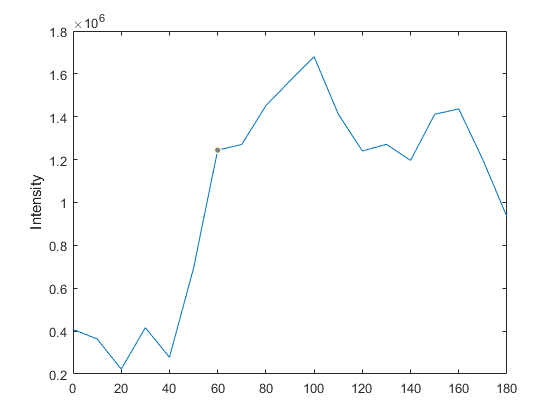

Tag = 'WKY214_4dAffine_11';
obj = Configuration3D(Tag);
timeInitial = obj.data_start;
timeFinal = obj.data_end;
nFiles = length(timeInitial:timeFinal);
            obj.loadVolume(timeInitial,1,timeFinal-1);
            T = timeInitial:timeFinal;
            Rho = zeros(1,nFiles);
            mask_brain = Mask(obj.pathMask, obj.isMaskFilled, obj.xRange,...
                        obj.yRange, obj.zRange);
            if obj.do_resize
                mask_brain = mask_brain.resize(obj.sizeFactor);
            end
            for i = 1:nFiles
                A = obj.Data(i).volume;
                A(mask_brain.contents == 0) = 0;
                Rho(i) = sum(A,'all');
            end
             for i = 2:2:nFiles-1
                 Rho(i) = (Rho(i-1)+Rho(i+1))/2;
             end
%                    Rho = medfilt1(Rho,10);
%            [rho_max, t_max] = max(Rho);
%            T_max = t_max + timeInitial-1;
%            T_diff = obj.timeInitial+obj.timeJump/2:obj.timeJump:obj.timeFinal+obj.timeJump/2;
%            Rho_diff = abs(Rho(obj.timeInitial+obj.timeJump:obj.timeJump:obj.timeFinal+obj.timeJump) - ...
%                Rho(obj.timeInitial:obj.timeJump:obj.timeFinal))./Rho(obj.timeInitial:obj.timeJump:obj.timeFinal);
            if obj.addSource
                switch obj.alphaFunctionalType
                    case 'auto'
                        T_alpha = diff;
                        alpha = (Rho_diff>0.5)*25000+(Rho_diff<=0.5).*(75000./(4*Rho_diff+1));
                    case 'manual'
                        T_alpha = obj.timeInitial:obj.timeFinal+obj.timeJump;
                        load(obj.pathAlpha);
                    otherwise
                        T_alpha = obj.timeInitial:obj.timeFinal+obj.timeJump;
                        alpha = ones(size(T_alpha))*obj.alpha;
                end
            end
            T = (T-1)*5;
            T_alpha = (T_alpha-1)*5;
            figure 
%            plot(T,Rho, T_max, rho_max, 'ro');
            plot(T,Rho);
            ylabel("Intensity")
%             hold on
%             p2 = plot(T_diff, Rho_diff*1e6);
%            hold on
%            plot([T_max, T_max],[0 rho_max],':m')
%            xticks(T);
            hold on
            anArrow = annotation('doublearrow') ;
            anArrow.Parent = gca;

            anArrow.Position = [(obj.timeInitial-1)*5, rho_max/2, (obj.timeFinal-obj.timeInitial+obj.timeJump-1)*5, 0];

Unrecognized function or variable 'rho_max'.

            line1 = annotation('line') ;
            line1.Parent = gca;
            line1.Position = [(obj.timeInitial-1)*5, 0, 0, Rho(obj.timeInitial)] ;
            line2 = annotation('line') ;
            line2.Parent = gca;
            line2.Position = [(obj.timeFinal+obj.timeJump-1)*5, 0, 0, Rho(obj.timeFinal+obj.timeJump)] ;
            %annotation('doublearrow',[(obj.timeInitial-1)/(timeFinal-1) (obj.timeFinal+1)/(timeFinal-1)],[1/2 1/2])
            %annotation('doublearrow',[0 1],[0 1])
            yyaxis right
            p3 = plot(T_alpha,alpha);
            text(T_alpha(1),alpha(1)+5000,num2str(alpha(1)));
            text(T_alpha(end)-20,alpha(end)+5000,num2str(alpha(end)));
            ylim([0 1e5])
            ylabel("\alpha")
            xlabel("Time(min)")
            xlim([-10,190])
%             legend([p2,p3],{'relative absolute difference * 10^6','\alpha'});
            title("Total intensity and \alpha over time");

## interpolated images

Tag = 'C294';
configuration = Configuration3D(Tag);
analysisConstants = loadJsonFile('scalarMap.json');
lagrangianSpecification = LagrangianSpecification(Tag,analysisConstants);

t = 1 (t1 = 31, t2 = 1 -> T = 31.000)
t = 2 (t1 = 31, t2 = 2 -> T = 31.200)
t = 3 (t1 = 31, t2 = 3 -> T = 31.400)
t = 4 (t1 = 31, t2 = 4 -> T = 31.600)
t = 5 (t1 = 31, t2 = 5 -> T = 31.800)
t = 6 (t1 = 31, t2 = 6 -> T = 32.000)
t = 7 (t1 = 31, t2 = 7 -> T = 32.200)
t = 8 (t1 = 31, t2 = 8 -> T = 32.400)
t = 9 (t1 = 31, t2 = 9 -> T = 32.600)
t = 10 (t1 = 31, t2 = 10 -> T = 32.800)
t = 11 (t1 = 33, t2 = 1 -> T = 33.000)
t = 12 (t1 = 33, t2 = 2 -> T = 33.200)
t = 13 (t1 = 33, t2 = 3 -> T = 33.400)
t = 14 (t1 = 33, t2 = 4 -> T = 33.600)
t = 15 (t1 = 33, t2 = 5 -> T = 33.800)
t = 16 (t1 = 33, t2 = 6 -> T = 34.000)
t = 17 (t1 = 33, t2 = 7 -> T = 34.200)
t = 18 (t1 = 33, t2 = 8 -> T = 34.400)
t = 19 (t1 = 33, t2 = 9 -> T = 34.600)
t = 20 (t1 = 33, t2 = 10 -> T = 34.800)
t = 21 (t1 = 35, t2 = 1 -> T = 35.000)
t = 22 (t1 = 35, t2 = 2 -> T = 35.200)
t = 23 (t1 = 35, t2 = 3 -> T = 35.400)
t = 24 (t1 = 35, t2 = 4 -> T = 35.600)
t = 25 (t1 = 35, t2 = 5 -> T = 35.800)
t = 26 (t1 = 35, t2 = 6 -> T = 3

ti = configuration.timeInitial;
tj = configuration.timeJump;
t1 = ti+9*tj;
nt = configuration.nt;
[RHO_t, U, R] = lagrangianSpecification.loadRomtResult(t1, configuration, analysisConstants.isInterpolated);
for t2 = 1:nt
TInd = ((t1 - ti) / tj) * nt + t2;

T = t1 + (t2 - 1) * (tj / nt);
fprintf('t = %d (t1 = %d, t2 = %d -> T = %.3f)\n', TInd, t1, t2, T);
d = reshape(RHO_t(:, t2), configuration.trueSize);
if analysisConstants.intensityRangeFlag
    d = d - min(d(:));
end
%make sure density is non-negative
d(d<0)=0;
mask_brain = Mask(configuration.pathStartpointsMask, configuration.isMaskFilled, configuration.xRange,...
                        configuration.yRange, configuration.zRange,1);
d(lagrangianSpecification.experimentMask.contents == 0) = 0;
d(mask_brain.contents == 0) = 0;
if ~isempty(configuration.pathAnatomyImage)
    anatomyImage = load_untouch_nii(configuration.pathAnatomyImage);

    anatomyImage = anatomyImage.img(configuration.xRange,...
                        configuration.yRange, configuration.zRange);
    if configuration.do_resize
         anatomyImage = resizeMatrix(anatomyImage, ...
            round(configuration.sizeFactor .* size(anatomyImage)), 'linear');
    end   
 else
    anatomyImage = Mask(configuration.pathMask, configuration.isMaskFilled,...
        configuration.xRange, configuration.yRange, configuration.zRange);
    if configuration.do_resize
         anatomyImage = anatomyImage.resize(configuration.sizeFactor);
    end    
    if configuration.dilate > 0
        anatomyImage = anatomyImage.dilate(configuration.dilate);
    end
    anatomyImage = anatomyImage.contents;               
end
vtkwrite(sprintf('./output/tmp/%s_images_E%d_t2=%d.vtk', configuration.tag, t1,t2), 'structured_points',...
    'mask', d);
end

t = 91 (t1 = 49, t2 = 1 -> T = 49.000)
t = 92 (t1 = 49, t2 = 2 -> T = 49.200)
t = 93 (t1 = 49, t2 = 3 -> T = 49.400)
t = 94 (t1 = 49, t2 = 4 -> T = 49.600)
t = 95 (t1 = 49, t2 = 5 -> T = 49.800)
t = 96 (t1 = 49, t2 = 6 -> T = 50.000)
t = 97 (t1 = 49, t2 = 7 -> T = 50.200)
t = 98 (t1 = 49, t2 = 8 -> T = 50.400)
t = 99 (t1 = 49, t2 = 9 -> T = 50.600)
t = 100 (t1 = 49, t2 = 10 -> T = 50.800)
